# Spectral Estimation: Welch-Linear

*Welch Method for estimation of the power spectrum of White Gaussian Noise*

**Configurate the path and clear the workspace, etc.**

clc; close all; clear;
addpath(genpath(fullfile('../')));

% IR Set with Duration = 1000ms
fs = 44100;
IRLen = 40;
dir = "aux_data/IR_Z_fixed/2s/"; % Azimuth
nameIRms = "IR44K_2s_1000ms";
IRms = struct2cell(load(dir+nameIRms));
IRms = IRms{1};
IRms =IRms(:,2);
IRms = [IRms{:}];

% PSD Welch Method parameters
segmentLength = 256;        % Segments will be 512 samples (goes to 257 when taking positive frequencies only)
noverlap = segmentLength/2; % 50 percent overlap
win = hamming(segmentLength);% 512 sample-length hanning window
N_bins = (segmentLength/2)+1;

f_500 = ceil(500/(fs/(N_bins*2)));
f_20k = ceil(20000/(fs/(N_bins*2)));
% N_bins = f_20k-f_500+1;

df = fs/(2*((segmentLength/2)+1));
f = 0:df:(fs-df)/2;
% f = f(f_500:f_20k);
N_noise_samples = 10;
N_augmentations = N_noise_samples*IRLen;% 100 noise samples * 40 augmentations = 4000 augmented samples

noise_aug_psd_reverb = zeros(N_bins,N_augmentations);
labels_reverb = zeros(N_augmentations,1);
vec = [1:6, 36:40; 6:16; 16:26; 26:36];
designSpecs = fdesign.lowpass('Fp,Fst,Ap,Ast', 20000, 22050, 0.01, 80, fs);
F = design(designSpecs);
for k = 1:N_noise_samples
    for i = 1:40
        % Augment noise sample
        noise = randn(fs,1);
        noise = filter(F,noise);
        index = ((k-1)*40) + i;
        noise_aug = conv(noise, IRms(:,i), 'same');
        
        % cut into 100ms frames with 50% overlap
        noise_windowed_fft  = welch_window(noise_aug,segmentLength,noverlap, win); % Perform windowing with 50% overlap and apply fft
        
        % Pyy
        Pyy = welch_input_fft(noise_windowed_fft, win, fs); % Calculate periodograms and average
        noise_aug_psd_reverb(:,index) = normalize(Pyy, 'range');
        labels_reverb(index) = i;
    end
end

## Example of PSD

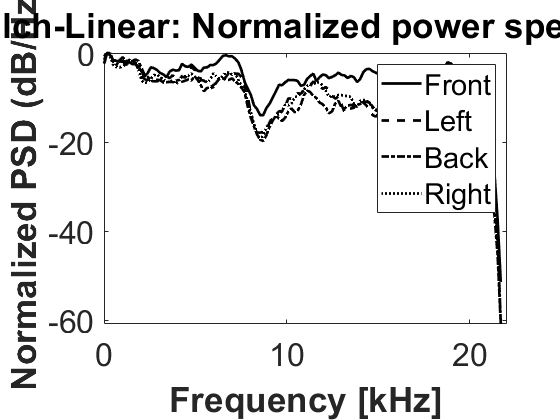

figure;
line = ["-", "--", "-.", ":"];
plot(f/1000, 10*log10(noise_aug_psd_reverb(:,1)),'k',"LineStyle",line(1),"LineWidth",2); hold on;
plot(f/1000, 10*log10(noise_aug_psd_reverb(:,11)),'k',"LineStyle",line(2),"LineWidth",2); hold on;
plot(f/1000, 10*log10(noise_aug_psd_reverb(:,21)),'k',"LineStyle",line(3),"LineWidth",2); hold on;
plot(f/1000, 10*log10(noise_aug_psd_reverb(:,31)),'k',"LineStyle",line(4),"LineWidth",2); hold on;
title("Welch-Linear: Normalized power spectrum",'FontSize',48);
xlabel("Frequency [kHz]",'FontSize',18,'FontWeight',"bold"); ylabel("Normalized PSD (dB/Hz)",'FontSize',24,'FontWeight',"bold");
xlim([0 22.050]);
legend("Front","Left", "Back", "Right");
ax = gca;
ax.FontSize = 24;

## **Probability Density functions of four direction: Front, Left, Back, Right**

Pyy_set_front = noise_aug_psd_reverb(:,ismember(labels_reverb,vec(1,:)));
Pyy_set_left = noise_aug_psd_reverb(:,ismember(labels_reverb,vec(2,:)));
Pyy_set_back = noise_aug_psd_reverb(:,ismember(labels_reverb,vec(3,:)));
Pyy_set_right = noise_aug_psd_reverb(:,ismember(labels_reverb,vec(4,:)));

N = size(vec,2)*N_augmentations/40;
mean_front = sum(Pyy_set_front,2)/N;
standard_deviation_front = sqrt(sum((Pyy_set_front-mean_front).^2, 2)/N);
pdf_front = zeros(size(Pyy_set_front));
pdf_front_normalized = zeros(size(Pyy_set_front));

mean_left = sum(Pyy_set_left,2)/N;
standard_deviation_left = sqrt(sum((Pyy_set_left-mean_left).^2, 2)/N);
pdf_left = zeros(size(Pyy_set_left));
pdf_left_normalized = zeros(size(Pyy_set_left));

mean_back = sum(Pyy_set_back,2)/N;
standard_deviation_back = sqrt(sum((Pyy_set_back-mean_back).^2, 2)/N);
pdf_back = zeros(size(Pyy_set_back));
pdf_back_normalized = zeros(size(Pyy_set_back));

mean_right = sum(Pyy_set_right,2)/N;
standard_deviation_right = sqrt(sum((Pyy_set_right-mean_right).^2, 2)/N);
pdf_right = zeros(size(Pyy_set_right));
pdf_right_normalized = zeros(size(Pyy_set_right));

% Assumed normal distribution
for i = 1:N_bins
    pdf_front(i,:) = normpdf(Pyy_set_front(i,:),mean_front(i),standard_deviation_front(i));
    pdf_left(i,:) = normpdf(Pyy_set_left(i,:),mean_left(i),standard_deviation_left(i));
    pdf_back(i,:) = normpdf(Pyy_set_back(i,:),mean_back(i),standard_deviation_back(i));
    pdf_right(i,:) = normpdf(Pyy_set_right(i,:),mean_right(i),standard_deviation_right(i));
    
    pdf_front_normalized(i,:) = normalize(pdf_front(i,:),'range');
    pdf_left_normalized(i,:) = normalize(pdf_left(i,:), 'range');
    pdf_back_normalized(i,:) = normalize(pdf_back(i,:), 'range');
    pdf_right_normalized(i,:) = normalize(pdf_right(i,:), 'range');
end

## PDF visualization

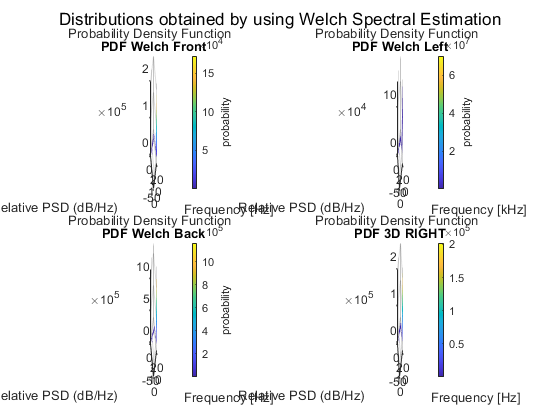

% Use meshgrid(X,Y,Z) to create a 3D-coordinates:
%   X: Relative dB
%   Y: Frequency
%   Z: Probability Density Function

X = repmat(f'/1000,1,N);
Y = 10*log10(Pyy_set_front);
Z = pdf_front;
figure;
subplot(2,2,1);surf(X,Y,Z);
C = colorbar;
ylabel(C,'probability');
shading interp
xlabel("Frequency [Hz]"); ylabel("Relative PSD (dB/Hz)"); zlabel("Probability Density Function"); title("PDF Welch Front");
X = repmat(f'/1000,1,N);
Y = 10*log10(Pyy_set_left);
Z = pdf_left;
subplot(2,2,2); surf(X,Y,Z);
C = colorbar;
ylabel(C,'probability');
shading interp
xlabel("Frequency [kHz]"); ylabel("Relative PSD (dB/Hz)"); zlabel("Probability Density Function"); title("PDF Welch Left");
X = repmat(f'/1000,1,N);
Y = 10*log10(Pyy_set_back);
Z = pdf_back;
subplot(2,2,3); surf(X,Y,Z);
C = colorbar;
ylabel(C,'probability');
shading interp
xlabel("Frequency [Hz]"); ylabel("Relative PSD (dB/Hz)"); zlabel("Probability Density Function"); title("PDF Welch Back");
X = repmat(f'/1000,1,N);
Y = 10*log10(Pyy_set_right);
Z = pdf_right;
subplot(2,2,4); surf(X,Y,Z);
ylabel(C, "probability");
C = colorbar;
shading interp
xlabel("Frequency [Hz]"); ylabel("Relative PSD (dB/Hz)"); zlabel("Probability Density Function"); title("PDF 3D RIGHT");
sgtitle("Distributions obtained by using Welch Spectral Estimation");

## Normalized PDF visualization

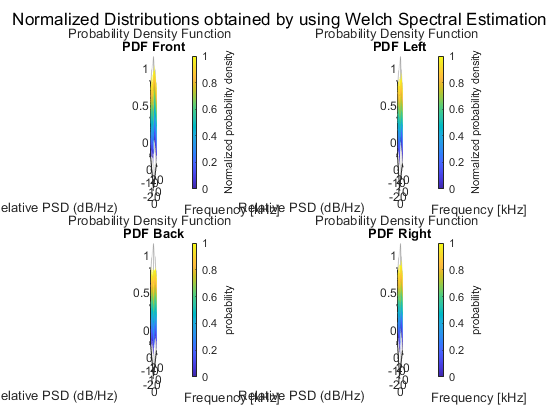

%   X: Relative dB
%   Y: Frequency
%   Z: Probability Density Function

X = repmat(f'/1000,1,N);
Y = 10*log10(Pyy_set_front);
Z = pdf_front_normalized;
figure;
subplot(2,2,1);surf(X,Y,Z);
C = colorbar;
ylabel(C,'Normalized probability density');
ylim([-25, 0]);
shading interp
xlabel("Frequency [kHz]"); ylabel("Relative PSD (dB/Hz)"); zlabel("Probability Density Function"); title("PDF Front");
X = repmat(f'/1000,1,N);
Y = 10*log10(Pyy_set_left);
Z = pdf_left_normalized;
subplot(2,2,2); surf(X,Y,Z);
C = colorbar;
ylabel(C,'Normalized probability density');
ylim([-25, 0]);
shading interp
xlabel("Frequency [kHz]"); ylabel("Relative PSD (dB/Hz)"); zlabel("Probability Density Function"); title("PDF Left");
X = repmat(f'/1000,1,N);
Y = 10*log10(Pyy_set_back);
Z = pdf_back_normalized;
subplot(2,2,3); surf(X,Y,Z);
C = colorbar;
ylabel(C,'probability');
ylim([-25, 0]);
shading interp
xlabel("Frequency [kHz]"); ylabel("Relative PSD (dB/Hz)"); zlabel("Probability Density Function"); title("PDF Back");
X = repmat(f'/1000,1,N);
Y = 10*log10(Pyy_set_right);
Z = pdf_right_normalized;
subplot(2,2,4); surf(X,Y,Z);
C = colorbar;
ylabel(C, "probability");
ylim([-25, 0]);
shading interp
xlabel("Frequency [kHz]"); ylabel("Relative PSD (dB/Hz)"); zlabel("Probability Density Function"); title("PDF Right");
sgtitle("Normalized Distributions obtained by using Welch Spectral Estimation");

## Most likely Power spectrum for each direction 

*We take the highest pdf value at each frequency bin to form the most likely representation for each direction*

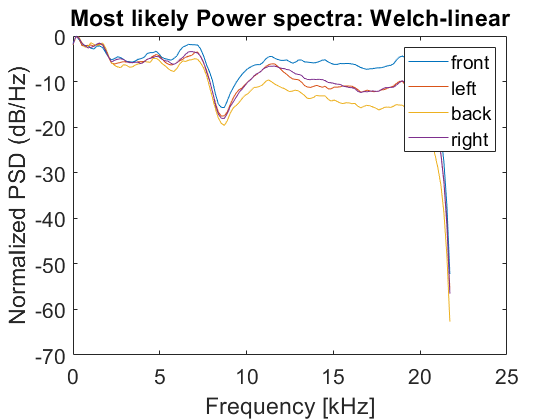

pyy_max = zeros(N_bins,4);
for i = 1:N_bins
    [val,idx] = max(pdf_front(i,:));
    pyy_max(i,1) = Pyy_set_front(i,idx);
    
    [val,idx] = max(pdf_left(i,:));
    pyy_max(i,2) = Pyy_set_left(i,idx);
    
    [val,idx] = max(pdf_back(i,:));
    pyy_max(i,3) = Pyy_set_back(i,idx);
    
    [val,idx] = max(pdf_right(i,:));
    pyy_max(i,4) = Pyy_set_right(i,idx);
end
figure;
for i = 1:4
    plot(f/1000, 10*log10(pyy_max(:,i))); hold on;
end
title("Most likely Power spectra: Welch-linear", "FontSize",32);
xlabel("Frequency [kHz]"); ylabel("Normalized PSD (dB/Hz)");
legend("front","left","back","right");
ax = gca;
ax.FontSize = 16;